# LAB SESSION 1: INTRODUCTION TO SIGNAL PROCESSING

## Biomedical Signals

#### **Student Names:**** Marta Maldonado and Marcos Oriol**

% Load data
addpath('routines/');

% Visualize ECG along time using command 'visualpvc'
load("data/ecgpvc.mat");
%visualpvc(ecgpvc);

## 1. Detecting PVC

In this section, an ECG signal with premature ventricular contractions (PVC) will be analyzed in order to detect the ectopic beats by using cross-correlation function.

Objective: detect automatically the ectopic beats using normalized cross-correation between the ECG signal and a 'representative' ectopic beat pattern.

#### **1.1. Representative Ectopic Beat Pattern**

This representative ectopic beat is built using the average of five ectopic beats. For this purpose, we have first detected 5 ectopic beats, which we are going to work on. Then, we have selected the time when the maximum value (corresponding to the R wave) appears, for each of the five selected beats, as can be seen in the following image:

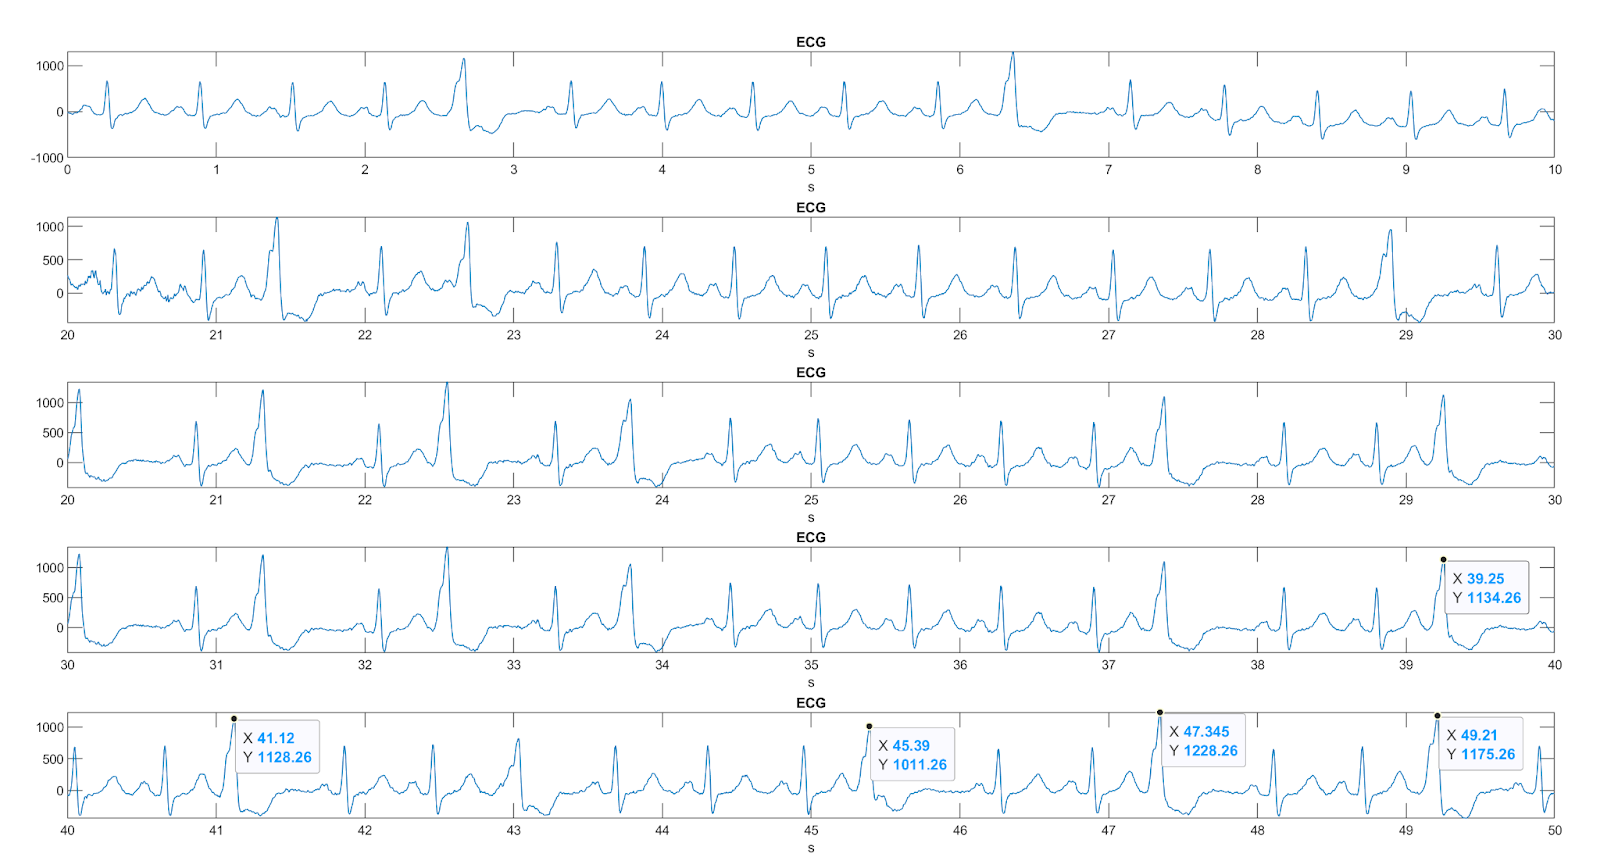

Then, we have fixed a sample window around the R wave, which includes the P and T waves of the beat.

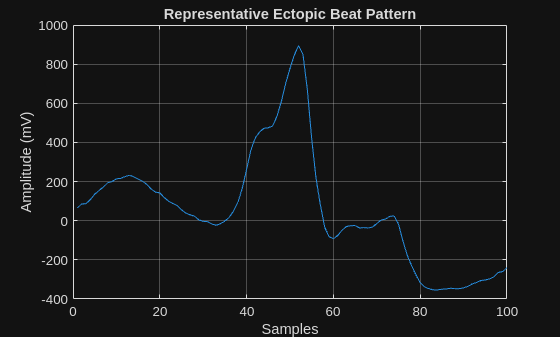

% Manually take the time of the R wave of 5 ectopic beats
peaks = [39.25, 41.12, 45.39,47.345 ,49.1 ];

% Parameters
fs = 200; % Sampling frequency
peak_samples = peaks * fs;
sample_window = 50; % window

% Extract a windor cenetered around the selected peaks
window_accum_values = zeros(sample_window*2, 1);
for i = peak_samples
    window = ecgpvc(i-sample_window:i+sample_window-1);
    window_accum_values = window_accum_values + window;
end

% Average of all detected ectopic beats
representative_beat = window_accum_values / length(peak_samples);

figure;
plot(representative_beat);
title('Representative Ectopic Beat Pattern');
xlabel('Samples');
ylabel('Amplitude (mV)');
grid on;

**1.2. Normalized Cross-Correlation**

Once we have calculated the pattern of the representative ectopic ECG beat, we now need to:

- Apply 'xcorr' between the ECG signal and the representative ectopic beat, to compute their similarity at each lag.

- Normalization.

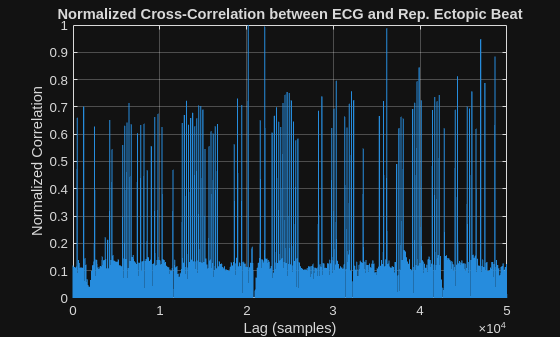

% Cross-correlation between 'ecgpvc' and 'representative_beat'
[corr, lags] = xcorr(ecgpvc, representative_beat);

% Since the full cross-correlation is symmetric, we keep the positive lags
trimmed_corr = corr(lags >= 0);

% Normalization
normalized_trim_corr = trimmed_corr / max(trimmed_corr);

figure;
plot(normalized_trim_corr);
title('Normalized Cross-Correlation between ECG and Rep. Ectopic Beat');
xlabel('Lag (samples)');
ylabel('Normalized Correlation');
ylim([0 1]);
grid on;

**1.3. Apply a threshold**

We now need to stablish a threshold in order to detect ectopic and normal beats. For this purpose, we have used two different methods:

- *islocalmax* function in Matlab

- *findpeaks* function in Matlab

We are going to use both methods, for the later comparison of the number of ectopic beats detected with each of them.

     A) *islocalmax*

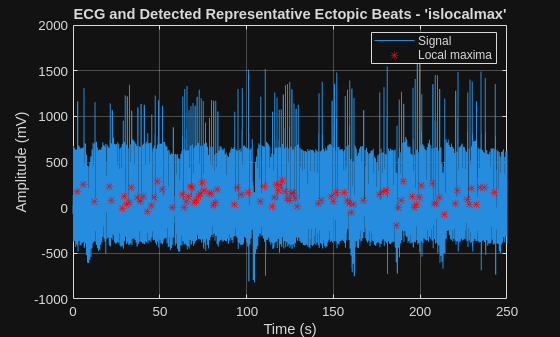

% Define the time knowing that the ECG signal was recorded during 250 seconds
record_duration = 250;
time = linspace(0, record_duration, 50000);

% Apply a threshold
threshold = 0.4;

% Find indxs above the threshold
idxs = find(normalized_trim_corr >= threshold);

% Find local maximum values of idxs
center_idx = find(islocalmax(normalized_trim_corr(idxs)) == 1);
max_samples = idxs(center_idx);
plot_local_max(ecgpvc, time, max_samples);
title("ECG and Detected Representative Ectopic Beats - 'islocalmax'");
xlabel('Time (s)');
ylabel('Amplitude (mV)');

In order to select the best threshold for detecting most of the ectopic beats present in the ECG signal, we tested different values while observing the resulting graph, similar to the one shown above with the ectopic beats marked with a red asterisk, in order to visually verify whether most of the ectopic beats were detected or not. After testing several threshold, we finally chose a **threshold of 0.4**, as almost all ectopic beats were detected, which we were able to verify by cosely inspecting the resulting graph obtained (the one shown above). With this configuration, a total of **92 ectopic beats** were detected.

If we look more closely at the final graph obtained (shown above) and zoom in (graph below), we can see that the red markers indicating the detected ectopic beats do not align exactly with the peaks of the ECG signal. This is because of how the cross-correlation function works, as the lag value obtained from this function representes where the start of the representative beat aligns with the ECG signal, but not the true peak of the ectopic beat. Therefore, since we have chosen a window that includes the P and T waves, we know that the R wave will lie within this window, not at the start of it. Consequently, although the red markers do not correspond precisely to the R wave, they indicate that an ectopic beat occurs close to each marker position.

                                         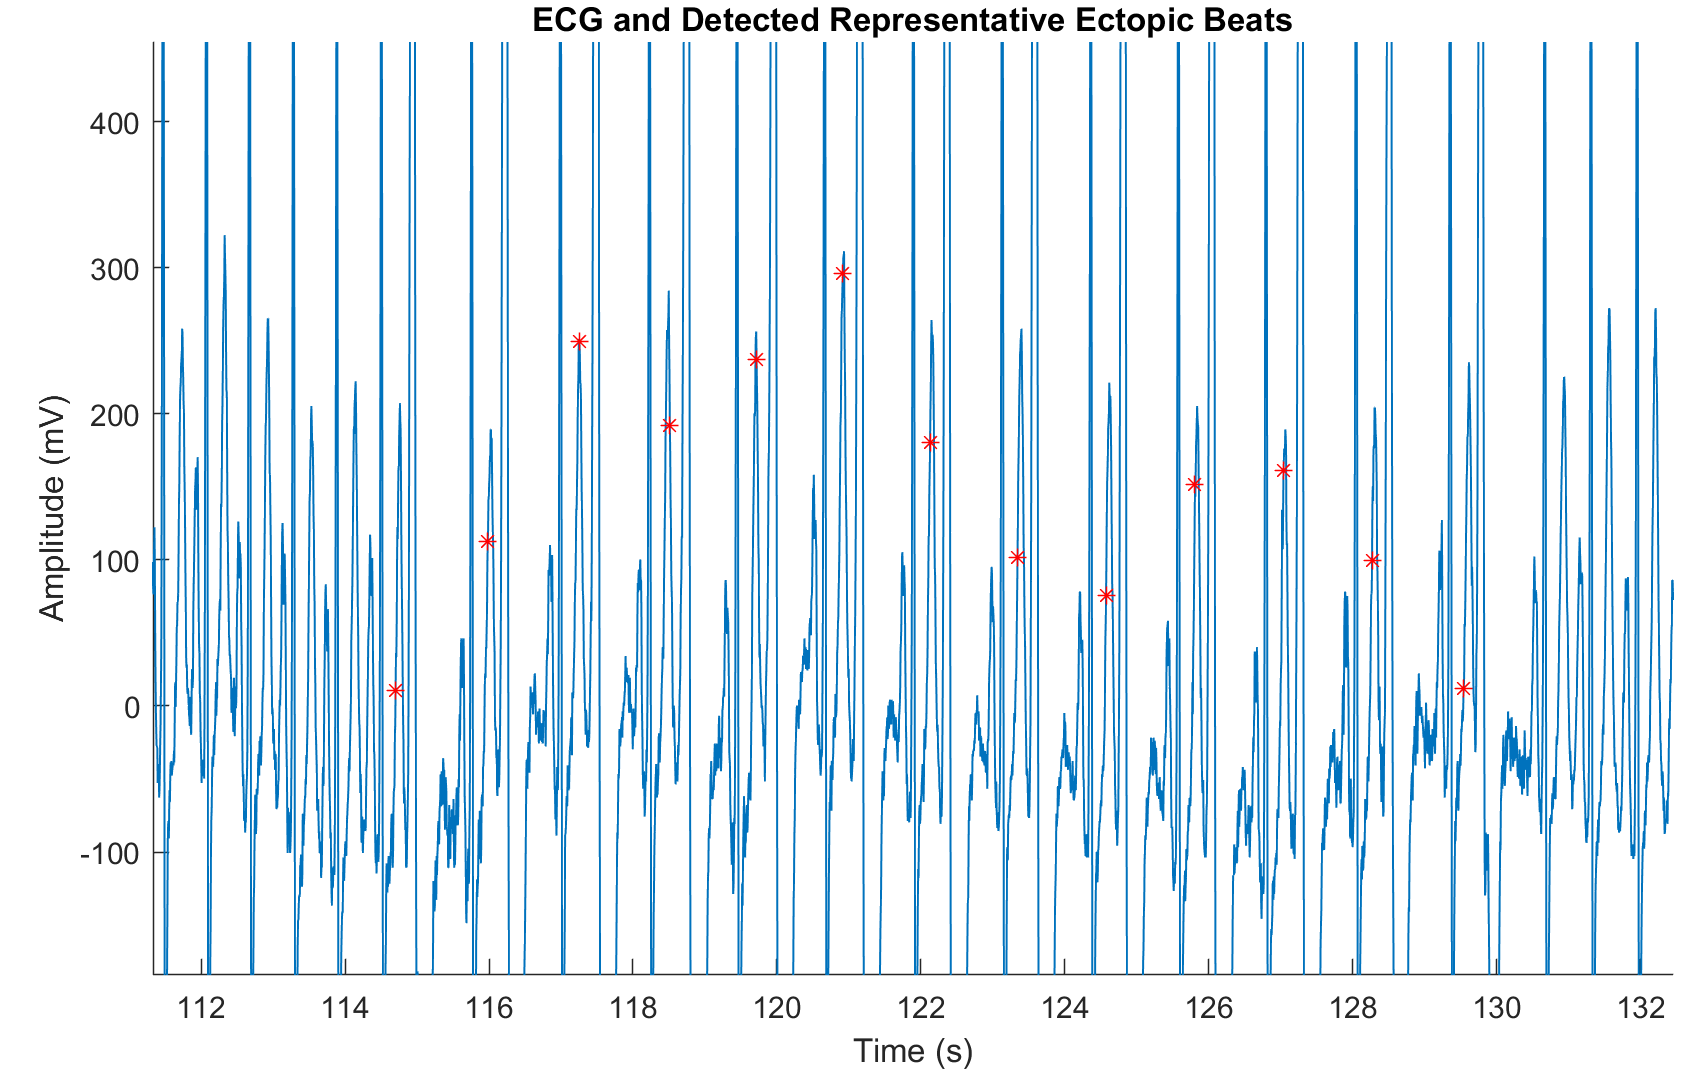

     B) *findpeaks:*

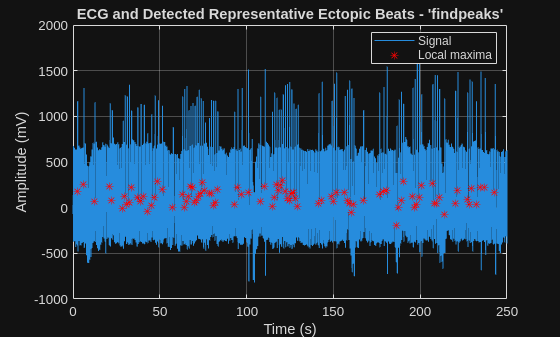

% Apply a threshold
threshold = 0.4; 

% Find indxs above the threshold
[~, idxs] = findpeaks(normalized_trim_corr, "MinPeakHeight", 0.4);

% Plot the detected ectopic beats
plot_local_max(ecgpvc, time, idxs);
title("ECG and Detected Representative Ectopic Beats - 'findpeaks'");
xlabel('Time (s)');
ylabel('Amplitude (mV)');

It can be observed that with this second method we are detecting the same number of ectopic beats: **92 ectopic beats**.

## 2. Filtering ECG

clear all;
clc;

load("data/ecgf.mat");
fs = 1000; %Hz


### Plot the data

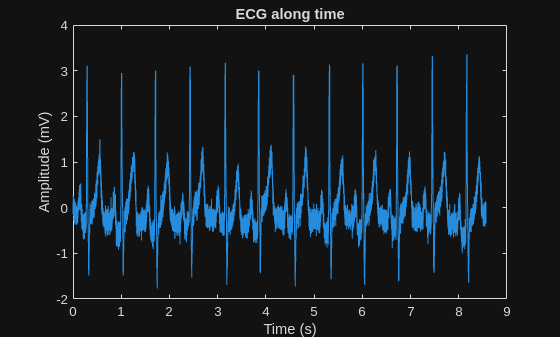

time = linspace(0, length(ecgf)/fs, length(ecgf));

figure;
plot(time, ecgf);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('ECG along time');

## Show noise

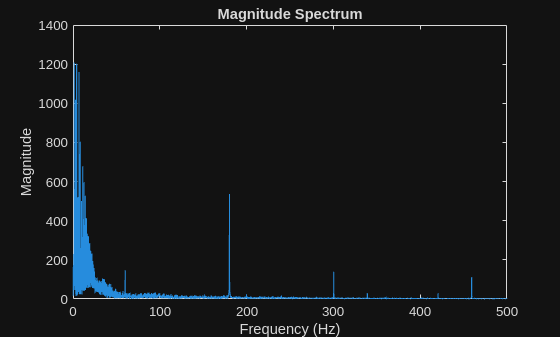

% We first compute the fft to see the most relevant frequencies in our
% signal.
[magnitude, f] = magnitude_spectrum(ecgf, fs);

figure;
plot(f, magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum');

## Apply low pass filter (order 4)

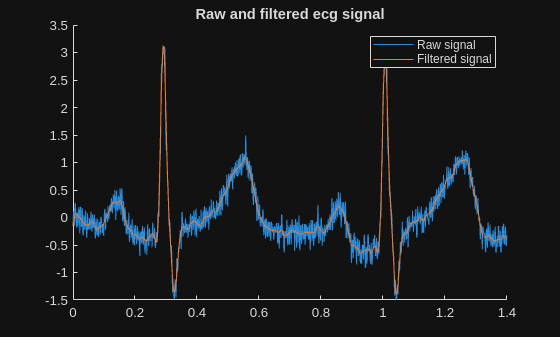

% Apply built in low pass filter
[b,a] = butter(4, 45/(fs/2), 'low');  % diseño del filtro
ecgff = filtfilt(b, a, ecgf); 
samples_to_plot = 1:1400;

figure;
hold on;
plot(time(samples_to_plot), ecgf(samples_to_plot));
plot(time(samples_to_plot), ecgff(samples_to_plot));
legend('Raw signal', 'Filtered signal')
title('Raw and filtered ecg signal')

## PSD of filtered signal

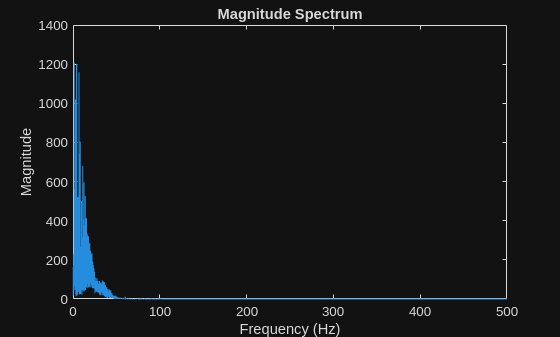

% Take the magnitude spectrum
[magnitudef, ff] = magnitude_spectrum(ecgff, fs);

figure;
plot(ff, magnitudef);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum');

## Filer Twave

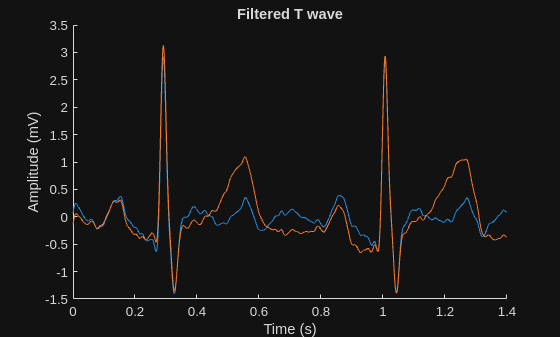

% Find the frequency of the T-wave and filter it from the signal

freq_limit = 5;
[b,a] = butter(4, freq_limit/(fs/2), "high");
filtered_t_waves = filtfilt(b, a, ecgff);
samples_to_plot = 1:1400;

figure;
hold on;
plot(time(samples_to_plot), filtered_t_waves(samples_to_plot));
plot(time(samples_to_plot), ecgff(samples_to_plot));
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Filtered T wave');

## IIR Filter Phase Test

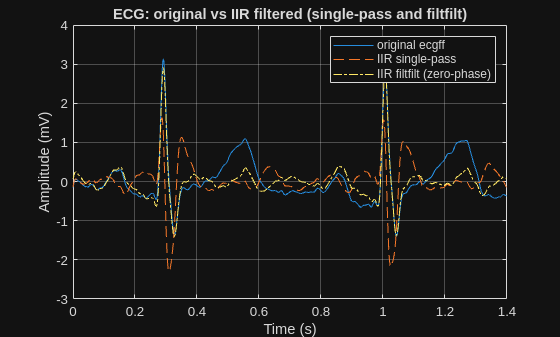

freq_limit = 5;        % cutoff in Hz 
[b_iir,a_iir] = butter(4, freq_limit/(fs/2), 'high'); % 4th-order highpass Butterworth

% Apply single-pass IIR and double-pass (zero-phase)
ecg_iir_single = filter(b_iir, a_iir, ecgff);    % single pass (causes phase distortion)
ecg_iir_filtfilt = filtfilt(b_iir, a_iir, ecgff);% zero-phase double-pass

% Time-domain overlay (zoom window)
samples_to_plot = 1:1400; % as you used, adjust if needed
figure;
plot(time(samples_to_plot), ecgff(samples_to_plot), 'DisplayName','original ecgff'); hold on;
plot(time(samples_to_plot), ecg_iir_single(samples_to_plot), '--', 'DisplayName','IIR single-pass');
plot(time(samples_to_plot), ecg_iir_filtfilt(samples_to_plot), '-.', 'DisplayName','IIR filtfilt (zero-phase)');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('ECG: original vs IIR filtered (single-pass and filtfilt)');
legend; grid on;

The single-pass filter, in this case filters better the T-wave, however, it also filters considerably the QRS complex. The zero-phase filtfilt leaves the QRS complex barely untouched.

This is due to the effect of the zero-phase filtering, as it runs the filter *forward* and then *backward, ***canceling the phase shift** introduced in the forward pass.

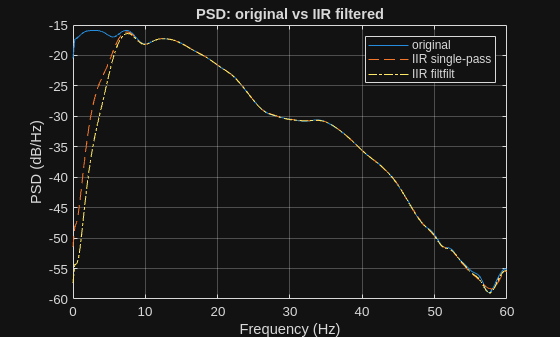

% PSD comparison via pwelch
nfft = 4096;
win = round(0.5*fs);
noverlap = round(0.25*fs);
[Px_orig,f] = pwelch(ecgff, win, noverlap, nfft, fs);
[Px_single,f] = pwelch(ecg_iir_single, win, noverlap, nfft, fs);
[Px_filtfilt,f] = pwelch(ecg_iir_filtfilt, win, noverlap, nfft, fs);

figure;
plot(f, 10*log10(Px_orig), 'DisplayName','original'); hold on;
plot(f, 10*log10(Px_single), '--', 'DisplayName','IIR single-pass');
plot(f, 10*log10(Px_filtfilt), '-.', 'DisplayName','IIR filtfilt');
xlim([0 60]); % zoom to relevant ECG band
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)');
title('PSD: original vs IIR filtered');
legend; grid on;

## Filter Order Increasing

In this exercise, we will compare IIR and FIR filters. IIR filt filt method achieves good filtering of the signal. However, a FIR filter with a defined order can be engineered to match the output of the IIR filter.

In this exercise we will:

- Get the target_reduction_dB obtained by the IIR implementation over the signal.

- Search for the FIR order that results the most similar to the IIR filter.


% Numeric metric: energy below 6 Hz (T-wave band)
T_band = [0 6];
orig_T_energy = bandpower(ecgff, fs, T_band);
single_T_energy = bandpower(ecg_iir_single, fs, T_band);
filtfilt_T_energy = bandpower(ecg_iir_filtfilt, fs, T_band);
fprintf('T-band energy reduction (dB): single-pass = %.2f dB, filtfilt = %.2f dB\n', ...
    10*log10(single_T_energy/orig_T_energy), 10*log10(filtfilt_T_energy/orig_T_energy));

T-band energy reduction (dB): single-pass = -9.24 dB, filtfilt = -13.02 dB



%% FIR comparison: start with order 4, then sweep orders to match filtfilt attenuation
orders = [4 8 16 32 64 128 256 512]; % pick candidates; adjust to your computation time
best_order = NaN; best_diff = Inf;
target_reduction_dB = 10*log10(filtfilt_T_energy/orig_T_energy); % negative number

fprintf('Target T-band reduction (IIR filtfilt): %.2f dB\n', target_reduction_dB);

Target T-band reduction (IIR filtfilt): -13.02 dB



for ord = orders
    % Design linear-phase FIR highpass
    b_fir = fir1(ord, freq_limit/(fs/2), 'high'); 
    ecg_fir = filtfilt(b_fir, 1, ecgff); % zero-phase FIR (recommended so no delay)
    
    % Compute PSD & T-band energy
    fir_T_energy = bandpower(ecg_fir, fs, T_band);
    fir_reduction_dB = 10*log10(fir_T_energy / orig_T_energy);
    fprintf('FIR order %3d -> T-band reduction: %.2f dB\n', ord, fir_reduction_dB);
    
    diff = abs(fir_reduction_dB - target_reduction_dB);
    if diff < best_diff
        best_diff = diff; 
        best_order = ord; best_ecg_fir = ecg_fir; 
        best_fir_reduction = fir_reduction_dB;
    end
end

FIR order   4 -> T-band reduction: -0.38 dB
FIR order   8 -> T-band reduction: -0.77 dB
FIR order  16 -> T-band reduction: -1.56 dB
FIR order  32 -> T-band reduction: -3.24 dB
FIR order  64 -> T-band reduction: -6.84 dB
FIR order 128 -> T-band reduction: -13.73 dB
FIR order 256 -> T-band reduction: -17.83 dB
FIR order 512 -> T-band reduction: -17.88 dB



fprintf('Best matching FIR order: %d (reduction %.2f dB, diff %.2f dB)\n', best_order, best_fir_reduction, best_diff);

Best matching FIR order: 128 (reduction -13.73 dB, diff 0.71 dB)


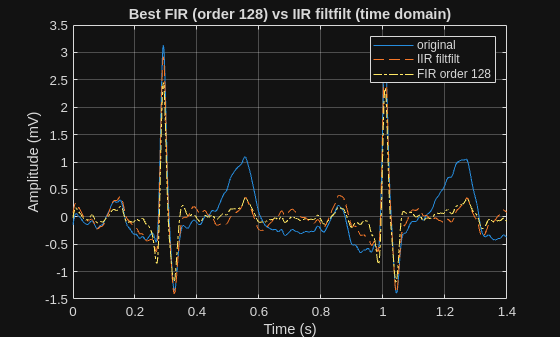


% Plot best FIR vs IIR filtfilt and original (time zoom)
figure;
plot(time(samples_to_plot), ecgff(samples_to_plot), 'DisplayName','original'); hold on;
plot(time(samples_to_plot), ecg_iir_filtfilt(samples_to_plot), '--', 'DisplayName','IIR filtfilt');
plot(time(samples_to_plot), best_ecg_fir(samples_to_plot), '-.', 'DisplayName', sprintf('FIR order %d', best_order));
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title(sprintf('Best FIR (order %d) vs IIR filtfilt (time domain)', best_order));
legend; grid on;

As it can be seen, the best matching order against filtfilt method is 128. This order makes that the filter output of both are the most similar possible among the different orders.

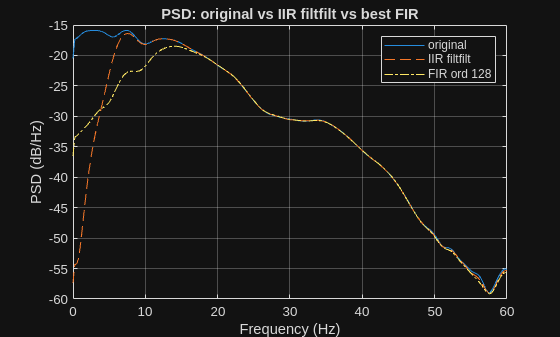


% PSD overlay for best FIR
[Px_fir, f] = pwelch(best_ecg_fir, win, noverlap, nfft, fs);
figure;
plot(f,10*log10(Px_orig), 'DisplayName','original'); hold on;
plot(f,10*log10(Px_filtfilt),'--','DisplayName','IIR filtfilt');
plot(f,10*log10(Px_fir),'-.','DisplayName', sprintf('FIR ord %d', best_order));
xlim([0 60]); xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)');
title('PSD: original vs IIR filtfilt vs best FIR'); legend; grid on;

The FIR PSD is slightly different, and will filter frequencies up to 15Hz, whereas the IIR filtfilt method is cleaner and adapts better to the signal.